clear
clc

小论文版本与大论文版本的主要区别在于，就体积流率q的计算中，没有展开接触宽度w与油膜厚度h，将其视为常数。此外，在摩擦热量Q的公式中，省去了微凸体数量N。

%%%%%%%%%%%%%%
%%% 物理量 %%%
%%%%%%%%%%%%%%

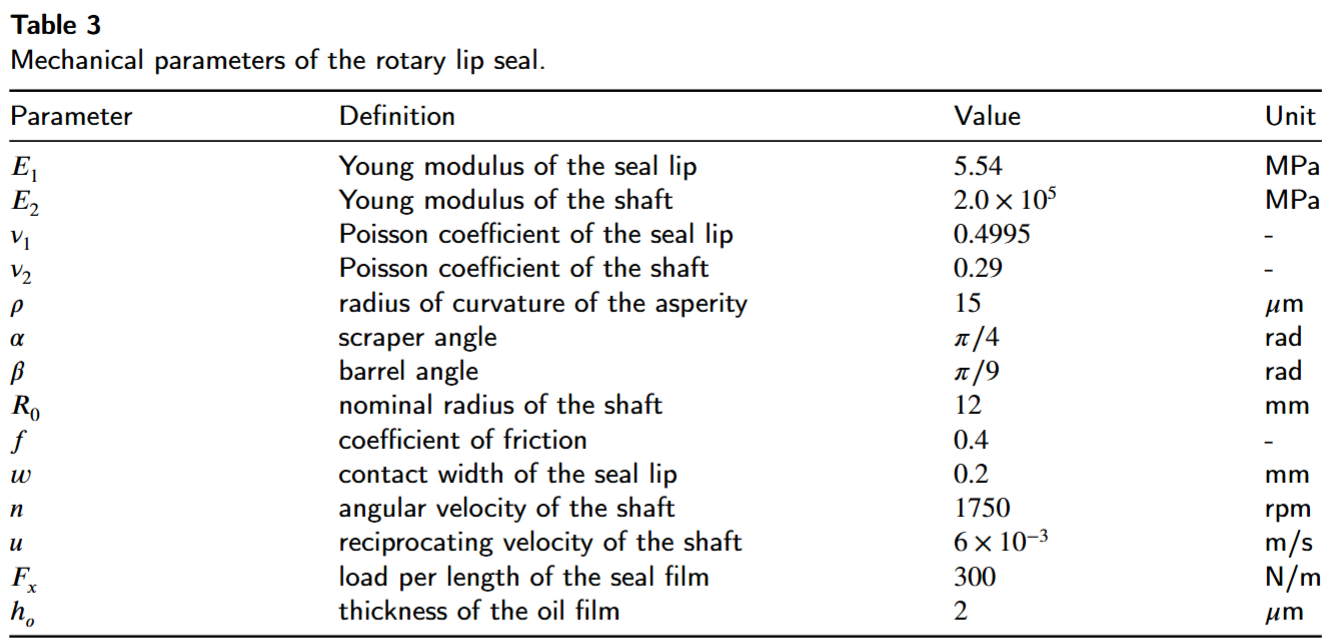

rou = 15e-6; % 微凸体尖端球面的曲率半径(m)%待修改
E1 = 5.54e6; % 柔性橡胶材料的杨氏模量(Pa)
E2 = 2e11; % 转轴金属材料的杨氏模量(Pa)
v1 = 0.4995; % 柔性橡胶材料的泊松比
v2 = 0.29; % 转轴金属材料的泊松比
f = 0.4; % 摩擦系数

alpha = pi/4; % 油液侧倾角(rad)
beta = pi/9; % 空气侧倾角(rad)
R0 = 12e-3; % 转轴标称半径(m)
H = 1.6e-3; % 卡紧弹簧截面形心到唇部底面之间的距离(m)
w = 0.2e-3; % 唇部标称接触宽度(m)
h = 2e-6; % 油膜厚度

I = 80; % 谐波减速器减速比
n = 1750; % 电机转速(r/min)
u = 6e-3; % 轴向往复运动的相对速度(m/s)

Fx = 300; % 单位长度的轴向载荷(N/m)                                                              修改2: 假定Fx为常数
p_oil = 10e6; % 油液压力(Pa)
mu0 = 71.3e-3; % 液压油的额定动力黏度(Pa·s)
alpha_mu = 1/(9.43e7+2.8e-1*p_oil); % 黏性压力系数(1/Pa)

mu = mu0*exp(alpha_mu*p_oil); % 实际动力黏度(Pa·s) 
E = 1/((1-v1^2)/E1+(1-v2^2)/E2); % 综合杨氏模量(Pa)

%%%%%%%%%%%%
%%% 作图 %%%
%%%%%%%%%%%%

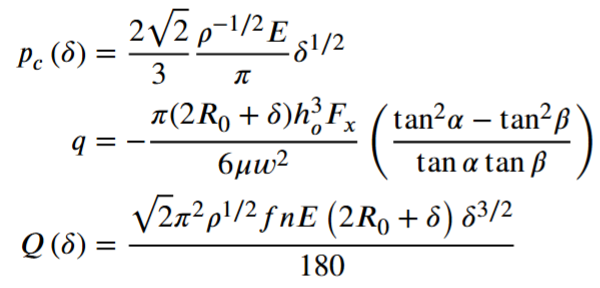

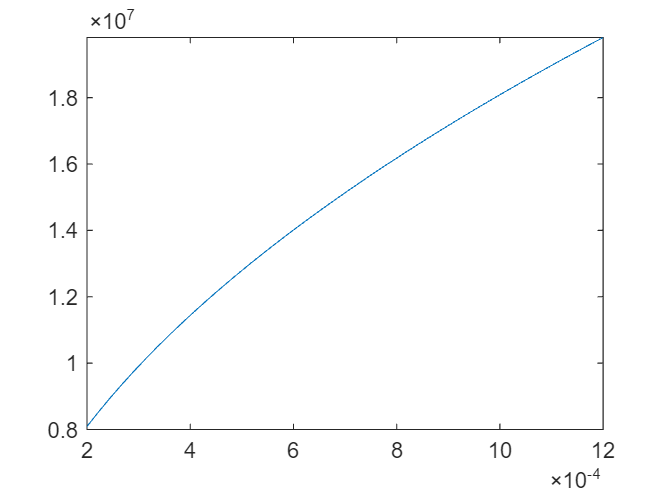

f_p_contact = @(delta_interf) 2*sqrt(2)*rou^(-1/2)*E*delta_interf^(1/2)/(3*pi);
f_q = @(delta_interf) abs(-((tan(alpha)^2-tan(beta)^2)/(tan(alpha)*tan(beta)))*(pi*(R0+delta_interf/2)*h^3*Fx)/(3*mu*w^2));
f_Q = @(delta_interf) sqrt(2)*pi^2*rou^(1/2)*f*n*E*(2*R0+delta_interf)*delta_interf^(3/2)/180;

fplot(f_p_contact,[0.2e-3, 1.2e-3]);

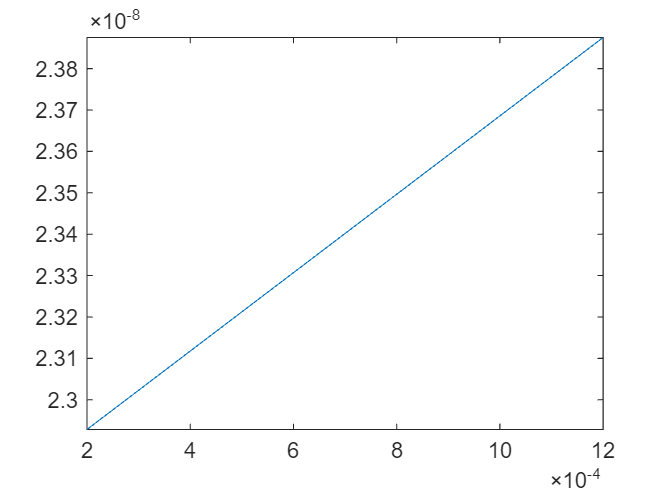

fplot(f_q,[0.2e-3, 1.2e-3]);

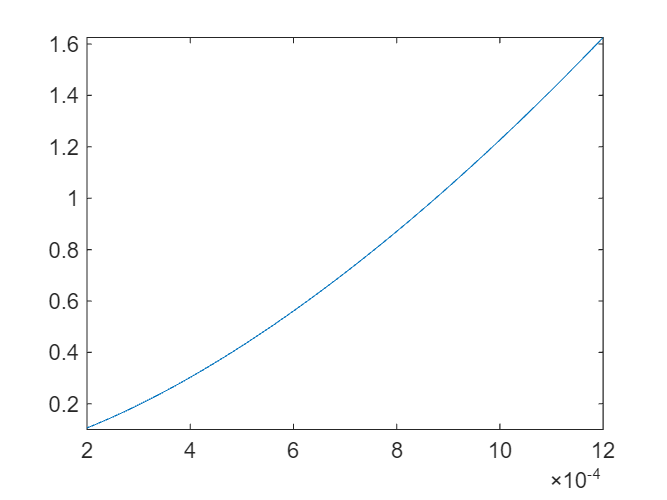

fplot(f_Q,[0.2e-3, 1.2e-3]);

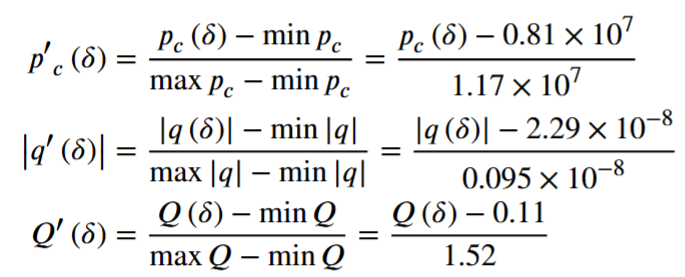

f_p_contact_normal = @(delta_interf) (2*sqrt(2)*rou^(-1/2)*E*delta_interf^(1/2)/(3*pi) - 0.81e7)/1.17e7;
                                                                                              
f_q_normal = @(delta_interf) -(abs(-((tan(alpha)^2-tan(beta)^2)/(tan(alpha)*tan(beta)))*(pi*(R0+delta_interf/2)*h^3*Fx)/(3*mu*w^2)) - 2.2928e-8)/0.09474e-8;% 绝对值

f_Q_normal = @(delta_interf) (sqrt(2)*pi^2*rou^(1/2)*f*n*E*(2*R0+delta_interf)*delta_interf^(3/2)/180 - 0.106216)/1.519344;
                                                                                               
fplot(f_p_contact_normal,[0.2e-3, 1.2e-3]);

hold on
fplot(f_q_normal,[0.2e-3, 1.2e-3]);
fplot(f_Q_normal,[0.2e-3, 1.2e-3]);

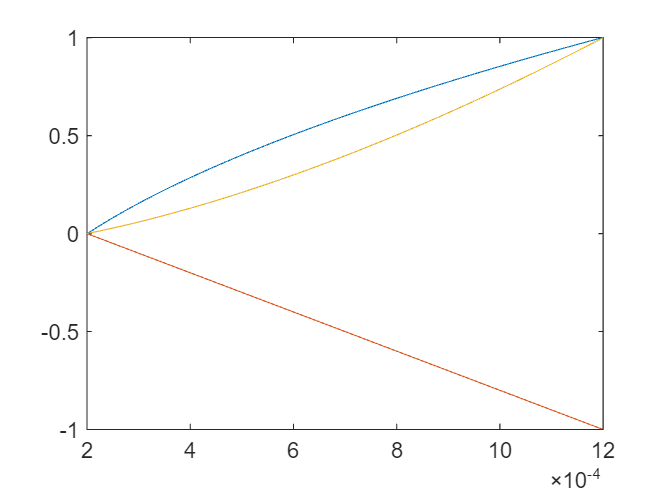

hold off


%%%%%%%%%%%%%%
%%% 归一化 %%%
%%%%%%%%%%%%%%

delta_interf = optimvar('delta_interf','LowerBound',0.2e-3,'UpperBound',1.2e-3);
f_p_contact = 2*sqrt(2)*rou^(-1/2)*E*delta_interf^(1/2)/(3*pi);
f_p_contact_normal = (f_p_contact - 0.81e7)/1.17e7;

f_q = ((tan(alpha)^2-tan(beta)^2)/(tan(alpha)*tan(beta)))*(pi*(R0+delta_interf/2)*h^3*Fx)/(3*mu*w^2);
f_q_normal = (f_q - 2.2928e-8)/0.09474e-8;                                        

f_Q = sqrt(2)*pi^2*rou^(1/2)*f*n*E*(2*R0+delta_interf)*delta_interf^(3/2)/180;                
f_Q_normal = (f_Q - 0.106216)/1.519344;                                                          

%%%%%%%%%%%%%%%%%
%%% 多目标优化 %%%
%%%%%%%%%%%%%%%%%

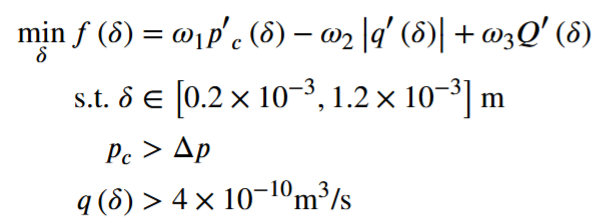

prob = optimproblem;
prob.Objective.first = f_p_contact_normal;
prob.Objective.second = -f_q_normal;
prob.Objective.third = f_Q_normal;

cons1 = f_p_contact >= 0.1967e5;
cons2 = f_q >= 4e-10;                                                                          % 修改9: 下限值
prob.Constraints.cons1 = cons1;
prob.Constraints.cons1 = cons2;

options = optimoptions('gamultiobj','FunctionTolerance',1e-6);
% rng default % For reproducibility
sol = solve(prob,'Options',options);

将使用 gamultiobj 求解问题。
gamultiobj stopped because it exceeded options.MaxGenerations.


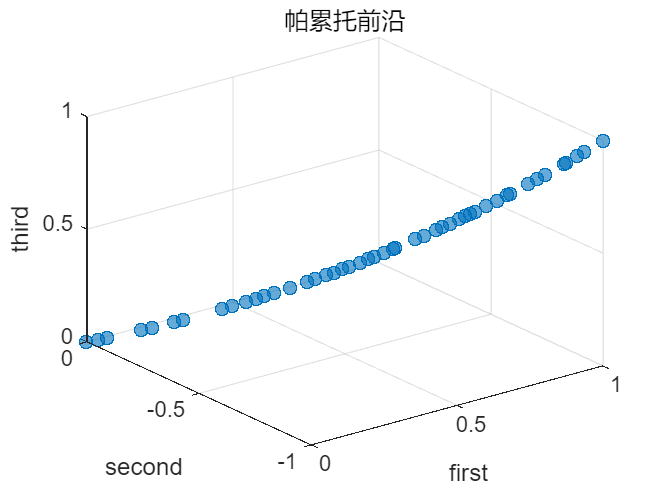

paretoplot(sol);